% dados da curva
sp_u = [20 25 30 35];
sp_h3 = [18.31 28.24 38.16 50.79];
sp_h4 = [25.71 38.5 50.78 65.52];
d_h = sp_h4-sp_h3;
sqrt_d_h = sqrt(sp_h4 - sp_h3);
% função interpolada de vazao
syms h3 h4 u dh
qi = piecewise(u<20,0,u>=20,16.4*u + 357.3)

$$qi = \left\{ \begin{array}{cl} 0 & \text{ if }u<20\\ \frac{82\,u}{5}+\frac{3573}{10} & \text{ if }20\leq u \end{array}\right.$$

sp_qi = vpa(subs(qi,u,sp_u),3)

$$sp\_qi = \left(\begin{array}{cccc} 685.0 & 767.0 & 849.0 & 931.0 \end{array}\right)$$

q12 = fit(sp_qi',d_h','poly1')

q12 =      Linear model Poly1:
     q12(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.0297  (0.0234, 0.03599)
       p2 =      -12.75  (-17.87, -7.632)

F_q12 = vpa(0.00297*sqrt(dh) - 12.75,4)

$$F\_q12 = 0.00297\,\sqrt{\mathrm{dh}}-12.75$$

plot(sp_u,vpa(subs(F_q12,dh,d_h),3))
sqrt_q12 = fit(sp_qi',sqrt_d_h','poly1');

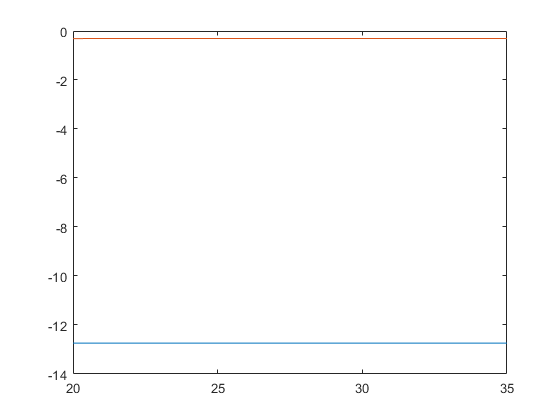

$$F\_sqrt\_q12 = 0.004515\,\mathrm{dh}-0.3211$$

F_sqrt_q12 = vpa(0.004515*(dh) - 0.3211,4)

plot(vpa(real(subs(subs(F_sqrt_q12,h3,sp_h3),h4,sp_h4)),4))

Error using plot
Data must be numeric, datetime, duration or an array convertible to double.

qout = fit(sp_qi',sp_h3','poly1');
F_qout = vpa(0.1309*sqrt(h3) - 71.95,4)
% Parâmetros
A1 = (pi*(31e-2)^2)/2;
syms z d
z = 2.5*pi*(h3 - 0.48);
d = -(h3 - 0.48)/sqrt(1.1);
A2 = vpa(expand(0.186*(0.837 - (1- z/2 + (z^4)/24 - (z^6)/720 + (z^8)/(720*56))*(1 - d + (d^2)/2 + (d^3)/6 + (d^4)/24))),5);

f1 = (qi - F_q12)/A1;
f2 = (F_q12 - F_qout)/A2;
% Pontos de operação:


% Espaço de Estados

%jacobiano
% A = double(subs(jacobian([f1;f2],[h4 h3]),[h4 h3 u],[sp_h4 sp_h3 sp_u]))
% B = double(subs(jacobian([f1;f2],u),[h4 h3 u],[sp_h4 sp_h3 sp_u]))
% %observação do estado 2 - h2
% C = [0 1];
% D = 0;
% tanque = ss(A,B,C,D); 